%Tính PSNR
psnr_wdrc = calc_psnr('HaM.wav', 'HaM_wdrc.wav');

✅ PSNR giữa "HaM.wav" và "HaM_wdrc.wav": 30.39 dB


psnr_mp3  = calc_psnr('HaM.wav', 'HaM_mp3.mp3');

✅ PSNR giữa "HaM.wav" và "HaM_mp3.mp3": 15.39 dB



fprintf('🔊 PSNR (WDRC) = %.2f dB\n', psnr_wdrc);

🔊 PSNR (WDRC) = 30.39 dB


fprintf('🎧 PSNR (MP3)  = %.2f dB\n', psnr_mp3);

🎧 PSNR (MP3)  = 15.39 dB


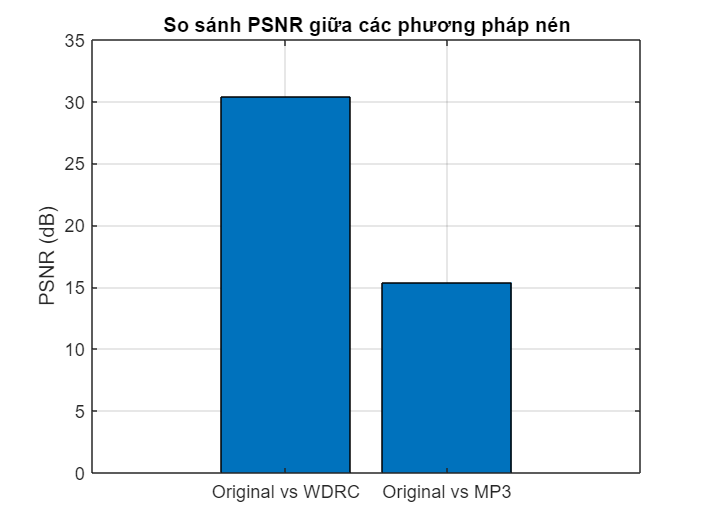


% Vẽ biểu đồ
methods = {'Original vs WDRC', 'Original vs MP3'};
psnr_values = [psnr_wdrc, psnr_mp3];

figure;
bar(psnr_values);
set(gca, 'xticklabel', methods);
ylabel('PSNR (dB)');
title('So sánh PSNR giữa các phương pháp nén');
grid on;